## Spring-mass-damper control system

Antti Paasi

This is a training project with the intention of creating a transfer function system model from scratch. A controller is designed to keep the system in set point. The system is tested with a sinusoidal input and step input.  

Consider a spring-mass-damper system with a driving force. The system can be described as


$$m\;\ddot{x} =-k\;x-c\;\dot{x} +u$$


Laplace transform of the system assuming initial states are zero


$$m\;\;s^2 \;X\left(s\right)=-k\;X\left(s\right)-c\;s\;X\left(s\right)+U\left(s\right)$$


Transfer function $P\left(s\right)=\frac{X\left(s\right)}{U\left(s\right)}$


$$P\left(s\right)=\frac{1}{m\;s^2 +c\;s+k}$$


For a critically damped system, damping coefficient $\zeta =\frac{c}{2\;m\;\omega_n }=1$ , where $\omega_n =\sqrt{\frac{k}{m}}$

Therefore, $c=2\;m\;\omega_{n\;} \;$

k = 210              ;  % N/m
m = 10               ;  % kg
wn = sqrt(k/m)       ;  % Natural frequency
c = 2*m*wn           ;  % kg/m
P = tf([1], [m,c,k]) ;


## Controller Design

We want to keep the system oscillating in a predefined frequency and amplitude. Assume a disturbing force $W\left(t\right)$ that needs to be compensated with a controller. $W\left(t\right)$ is modeled as a random noise source. As the system's preset value is a sinewave, we will use a PD-controller.

A PD-control can be described in the time domain as


$$u\left(t\right)=k_p +k_d \;\dot{e}$$
 

Laplace transform:


$$U\left(s\right)=k_p E\left(s\right)+k_d \;s\;E\left(s\right)$$


Transfer function $H\left(s\right)=\;\frac{U\left(s\right)}{E\left(s\right)}$:


$$H\left(s\right)=k_p +k_d \;s$$
 

To limit loop gain at high frequencies, let's add a small time constant $T$ 


$$H\left(s\right)=k_p +\frac{k_d s}{T\;s+1}$$
  

Open-loop system transfer function


$$G_o \left(s\right)=H\left(s\right)P\left(s\right)$$
   

Initial guesses for $k_p$ and $k_d$ , later tweaked manually to adjust performance

T = 0.5    ;  %  time constant
kp = 20    ;    %  proportional gain
kd = 10    ;      %  derivative gain

H = tf([kp*T+kd, kp], [T, 1]) ; 
G_o = series(P,H) ;

Open-loop stability is verified with poles

poles_o = pole(G_o)

poles_o =    -4.5826
   -4.5826
   -2.0000


The system is stable. 

Closed-loop transfer function:


$$G_c =\frac{H\;P}{1+H\;P}\;$$


G_c = H*P/(1+H*P) ;

Closed loop stability

poles_c = pole(G_c)

poles_c =   -4.7434 + 2.2155i
  -4.7434 - 2.2155i
  -4.5826 + 0.0000i
  -4.5826 + 0.0000i
  -2.0000 + 0.0000i
  -1.6783 + 0.0000i


Stable as well. 

System characteristics

system_info = stepinfo(G_c)

system_info = struct with fields:
         RiseTime: 0.2819
    TransientTime: 2.4874
     SettlingTime: 2.4874
      SettlingMin: 0.0806
      SettlingMax: 0.1099
        Overshoot: 26.3785
       Undershoot: 0
             Peak: 0.1099
         PeakTime: 0.7767


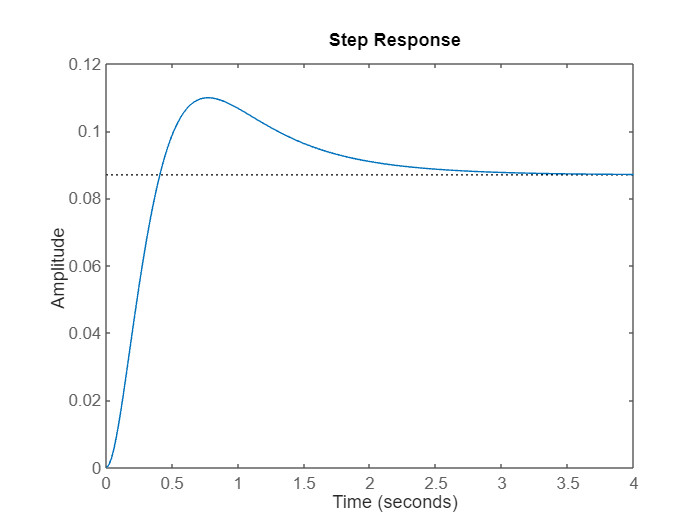

step(G_c)

## Simulation model

Let's use our closed-loop system transfer function and create a Simulink model. Add a random noise signal. Simulate with sine and step inputs.

num = G_c.numerator{1,1} ;   % tf numerator
den = G_c.denominator{1,1} ; % tf denominator
A = 20     ;   % input amplitude
f = wn     ;   % input frequency

setmax = system_info.SettlingMax ;
gain = A/setmax ;   % Gain term to scale the output with the input. Otherwise output amplitude would be very small.

Run the simulation in Simulink. Plot input and output data.

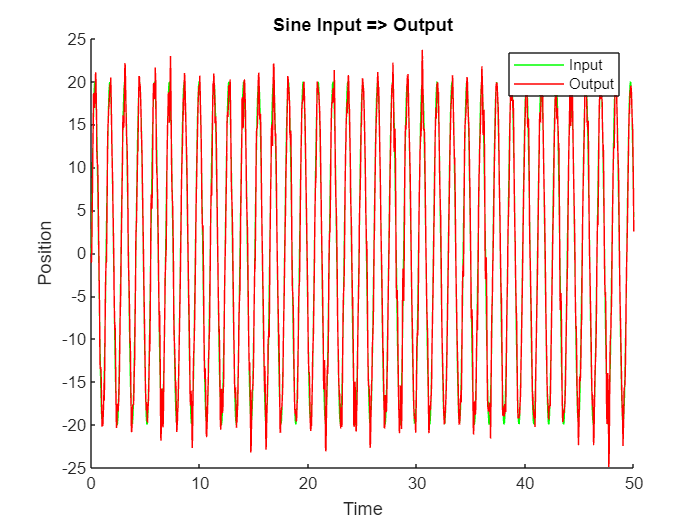

simOut = sim('springmassdamper_sim.slx') ; 
in_sine = simOut.input_sine    ;
out_sine = simOut.output_sine  ;
in_step = simOut.input_step    ;
out_step = simOut.output_step  ;

figure
hold on
title('Sine Input => Output')
xlabel('Time')
ylabel('Position')

plot(in_sine, 'green')
plot(out_sine, 'red')
legend('Input', 'Output')
hold off

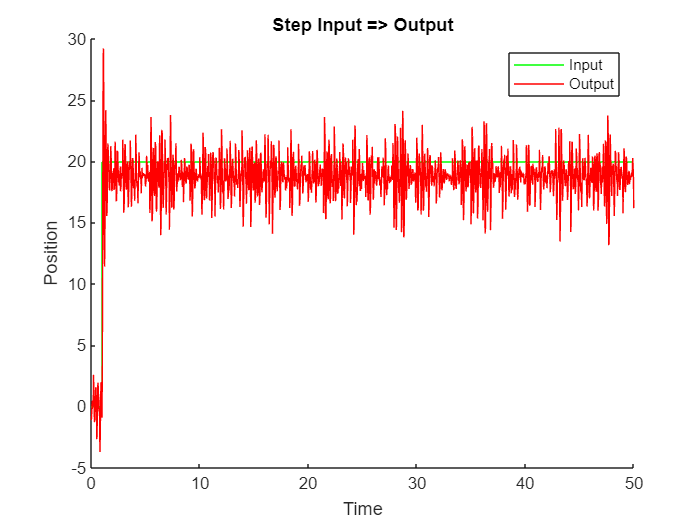

figure
hold on
title('Step Input => Output')
xlabel('Time')
ylabel('Position')

plot(in_step, 'green')
plot(out_step, 'red')
legend('Input', 'Output')

## Results

The system output follows a sine input nicely despite the noise. A step input is harder to follow and the system oscillates around the set point. Noise affects the step input system more. After all, it's not very natural for a spring system to stay in one position. Overall, the system performance is OK.   